Approximations of mean and covariance

close all;
clear all;
clc

N = 10000; % at least 10000
%set different kinds of distribution
distribution_type = 2;
%set nonlinear filter mode
type = 'UKF'% 'UKF','EKF','CKF'

type = 'UKF'

if distribution_type == 1
    x_mu = [125 125]';
    x_sigma = diag([10^2 5^2]);
elseif distribution_type == 2
    x_mu = [-25 125]';
    x_sigma = diag([10^2 5^2]); 
elseif distribution_type == 3
    x_mu = [60 60]';
    x_sigma = diag([10^2 5^2]);  
end
%sensor location
s_1 = [0 100]';
s_2 = [100 0]';
sigma = diag([0.1*pi/180 0.1*pi/180].^2);

%measurement model y = hx+r
h = @(x) dualBearingMeasurement(x,s_1,s_2);
%use samples to approximate the mean and covariance directly.
[y_mu,y_sigma, y_sample, x_sample] = gaussianapproximate(x_mu, x_sigma, @(x)genNonLinearMeasurementSequence(x,h,sigma),N);
y_mu ,y_sigma

y_mu =     2.3286
    2.3553


y_sigma =     0.0556    0.0103
    0.0103    0.0020



%use nonlinear filter to approximate
if strcmp(type,'UKF') || strcmp(type,'CKF')
    [sp,w] = sigmaPoints(x_mu,x_sigma,type);
    hsp = h(sp);
    [ykf_mu,ykf_sigma] = calculatesp(h,sigma,sp,w);
elseif strcmp(type,'EKF')
    [hx, dhx] = h(x_mu);
    ykf_mu = hx;
    ykf_sigma = dhx*x_sigma * dhx' + sigma;
end
ykf_mu, ykf_sigma

ykf_mu =     2.3269
    2.3550


ykf_sigma =     0.0600    0.0108
    0.0108    0.0020


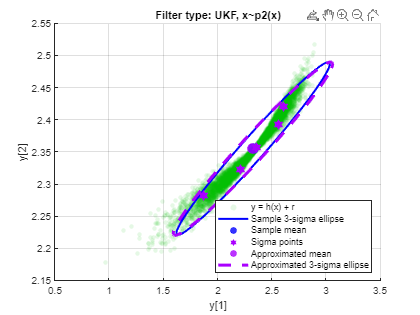


%plot the figure
newcolors = {'#0B0','#00F','#50F','#A0F','#F00','#F80','#FF0'};
colororder(newcolors);
cp = get(gca,'ColorOrder');

grid on; hold on 
sc1 = scatter(y_sample(1,:), y_sample(2,:), 20, 'filled', 'MarkerFaceColor', cp(1,:), 'MarkerFaceAlpha',0.1, 'DisplayName','y = h(x) + r');
[ xy ] = sigmaEllipse2D( y_mu, y_sigma, 3, 100 );
p1 = plot(xy(1,:),xy(2,:), 'Color', cp(2,:), 'LineWidth',2, 'DisplayName','Sample 3-sigma ellipse');
sc2 = scatter(y_mu(1), y_mu(2), 100, 'o', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(2,:), 'MarkerEdgeColor', cp(2,:),'DisplayName','Sample mean');
if strcmp(type,'UKF') || strcmp(type,'CKF')
    sc3 = scatter(hsp(1,:), hsp(2,:), 100, 'h','filled', 'MarkerFaceAlpha',1, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','Sigma points');
end
sc4 = scatter(ykf_mu(1,:), ykf_mu(2,:), 100, 'o','filled', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','Approximated mean');
[ xy ] = sigmaEllipse2D( ykf_mu, ykf_sigma, 3, 100 );
p2 = plot(xy(1,:),xy(2,:), '--', 'Color', cp(4,:), 'LineWidth',3,'DisplayName','Approximated 3-sigma ellipse');

xlabel 'y[1]', ylabel 'y[2]'
title(sprintf('Filter type: %s, x~p%d(x)',type,distribution_type))
legend('Location','southeast')

Nonlinear KF

%initialize
s_1 = [-200,100]';
s_2 = [-200,-100]';
T = 1;
x_0 =  [0 0 20 0 5*pi/180]';
P_0 = diag([10 10 2 pi/180 pi/180].^2);
N = 100;
%set noise type label 1, 2, 3
noise_type = 3;
sigma_v = 1;
sigma_w = pi/180;
if noise_type==1
    sigma_phi1 = 2*pi/180
    sigma_phi2 = 2*pi/180
elseif noise_type == 2
    sigma_phi1 = 2*pi/180
    sigma_phi2 = 0.1*pi/180
elseif noise_type == 3
    sigma_phi1 = 0.1*pi/180
    sigma_phi2 = 0.1*pi/180
end

sigma_phi1 = 0.0017

sigma_phi2 = 0.0017

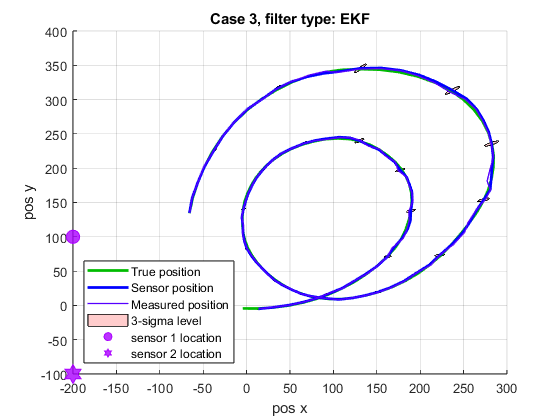

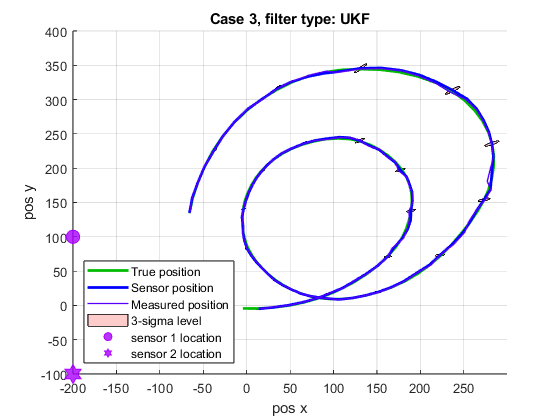

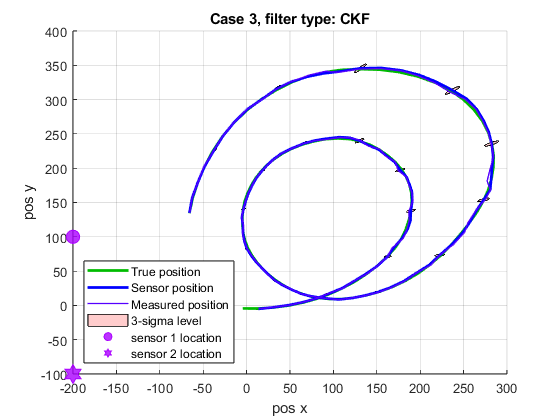

%coordinated turn model
Q = diag([0 0 T*sigma_v^2 0 T*sigma_w^2]);
R = diag([sigma_phi1 sigma_phi2].^2);

% generate state sequence
f = @(x) coordinatedTurnMotion(x,T);
X = genNonLinearStateSequence(x_0,P_0,f,Q,N);
% generate measurement sequence
h = @(x) dualBearingMeasurement(x,s_1,s_2);
Y = genNonLinearMeasurementSequence(X,h,R);

% measured positions
mp(1,:) = ( s_2(2)-s_1(2) + tan(Y(1,:))*s_1(1) - tan(Y(2,:))*s_2(1) ) ./ ( tan(Y(1,:)) - tan(Y(2,:)) );
mp(2,:) = s_1(2) + tan(Y(1,:)) .* ( mp(1,:) - s_1(1) );



for type = {'EKF','UKF','CKF'}

    % filter
    [xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, type{1});
    figure()
    grid on; hold on

    for i=1:5:length(xf)
        ell_xy = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,50);
        p4 = fill(ell_xy(1,:),ell_xy(2,:), cp(5,:),'facealpha',.2, 'DisplayName','3-sigma level'); 
    end

    p1 = plot(X(1,:),X(2,:), 'Color', cp(1,:), 'LineWidth',2, 'DisplayName','True position');
    p2 = plot(xf(1,:),xf(2,:), 'Color', cp(2,:), 'LineWidth',2, 'DisplayName','Sensor position');
    
    sc1 = scatter(s_1(1), s_1(2), 100, 'o', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 1 location');
    sc2 = scatter(s_2(1), s_2(2), 200, 'h', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 2 location');
    
    axis manual
    p3 = plot(mp(1,:),mp(2,:), 'Color', [cp(3,:) 0.8], 'LineWidth',1, 'DisplayName','Measured position');
    
    xlabel 'pos x', ylabel 'pos y'
    title(sprintf('Case %d, filter type: %s',noise_type,type{1}))
    legend([p1 p2 p3 p4 sc1 sc2], 'Location','southwest')


end

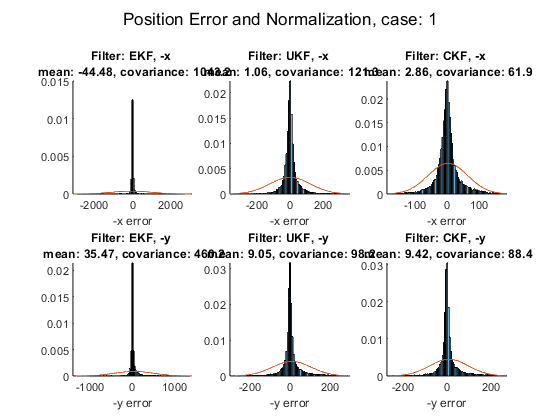

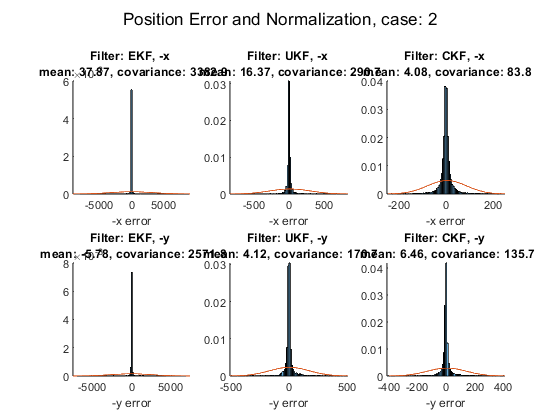

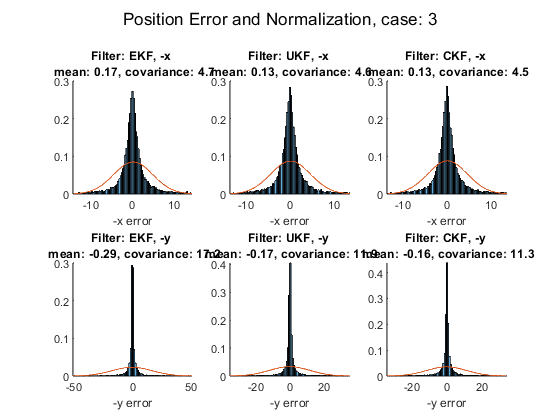


MC = 150;
type = {'EKF','UKF','CKF'};
est_err = cell(3,3);
for imc = 1:MC
    for noise_type = 1:3
        sigma_v = 1;
        sigma_w = pi/180;
        if noise_type==1
            sigma_phi1 = 2*pi/180;
            sigma_phi2 = 2*pi/180;
        elseif noise_type == 2
            sigma_phi1 = 2*pi/180;
            sigma_phi2 = 0.1*pi/180;
        elseif noise_type == 3
            sigma_phi1 = 0.1*pi/180;
            sigma_phi2 = 0.1*pi/180;
        end
        %coordinated turn model
        Q = diag([0 0 T*sigma_v^2 0 T*sigma_w^2]);
        R = diag([sigma_phi1 sigma_phi2].^2);
        
        % generate state sequence
        f = @(x) coordinatedTurnMotion(x,T);
        X = genNonLinearStateSequence(x_0,P_0,f,Q,N);
        % generate measurement sequence
        h = @(x) dualBearingMeasurement(x,s_1,s_2);
        Y = genNonLinearMeasurementSequence(X,h,R);
        for itype = 1:numel(type)
            [xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,type{itype});
            % Save the estimation errors and the prediction errors
            est_err{noise_type,itype}(1:2,end+1:end+length(xf)) = X(1:2,2:end) - xf(1:2,:);
        end
    end
end            
close all;

bins = 100;
close all;
pos = {'x','y'};
for noise_type = 1:3
    figure()
    sgtitle(sprintf('Position Error and Normalization, case: %d',noise_type))
    for itype = 1:numel(type)
        for ipos = 1:numel(pos)
            subplot(2,3, itype + (ipos-1)*numel(type) );
            hold on;
            
            idata = est_err{noise_type,itype}(ipos,:);
            mu  = mean(idata);
            stddev = std(idata);
            
            % remove outliers
            idx = abs(idata-mu) < stddev*3;
            idata = idata(idx);
            
            histogram( idata, bins ,'Normalization','pdf','DisplayName','histogram MSE of position error norm');
            
            [x,y] = normpdf2(mu, stddev^2, 3, 100);
            plot(x,y, 'LineWidth',0.5, 'DisplayName', sprintf('gaussian N(x; 0, $P_{N|N})$') );
            
            xlims = max(abs(idata));
            xlim([-xlims xlims]);
            
            xlabel(sprintf('-%s error',pos{ipos}))
            title(sprintf('Filter: %s, -%s \n mean: %.2f, covariance: %.1f',type{itype},pos{ipos},mu,stddev ))    
        end
    end
end

% close all;

Tuning nonlinear filters

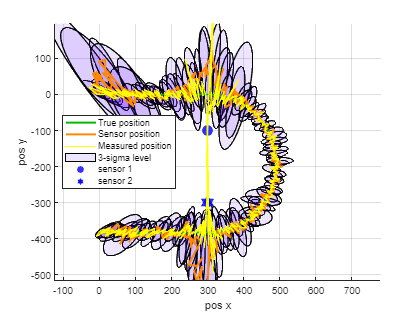

close all;
clear all;
clc
%initialize
T = 0.1;
K = 600;
omega = zeros(1,K+1);
omega(150:450) = -pi/301/T;
x0 = [0 0 20 0 omega(1)]';
X = zeros(length(x0),K+1);
X(:,1) = x0;
for i = 2:K+1
    X(:,i) = coordinatedTurnMotion(X(:,i-1),T);
    X(5,i) = omega(i);
end
%tuning parameter
%sigma_v = 0.001;
%sigma_w = pi/180;
%sigma_v = 0.00001;
%sigma_w = pi/18000;
sigma_v = 1000;
sigma_w = pi/180*1000;
x_0 = [0 0 0 0 0]';
P_0 = diag([10 10 10 5*pi/180 pi/180].^2);
s_1 = [300 -100]';
s_2 = [300 -300]';
R = diag([pi/180 pi/180].^2);
Q = diag([0 0 T*sigma_v^2 0 T*sigma_w^2]);

% generate state sequence
f = @(x) coordinatedTurnMotion(x,T);
% generate measurement sequence
h = @(x) dualBearingMeasurement(x,s_1,s_2);
Y = genNonLinearMeasurementSequence(X,h,R);
%according to previous answers, generally CKF is better.
[xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,'CKF');

%follow the pdf instructions
Xm(1,:) = ( s_2(2)-s_1(2) + tan(Y(1,:))*s_1(1) - tan(Y(2,:))*s_2(1) ) ./ ( tan(Y(1,:)) - tan(Y(2,:)) );
Xm(2,:) = s_1(2) + tan(Y(1,:)) .* ( Xm(1,:) - s_1(1) );

%plot
figure();
grid on; hold on;
newcolors = {'#0B0','#F80','#FF0','#00F','#50F','#A0F','#F00'};
colororder(newcolors);
cp = get(gca,'ColorOrder');

for i=1:5:length(xf)
    ell_xy = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,50);
    p4 = fill(ell_xy(1,:),ell_xy(2,:), cp(5,:),'facealpha',.1, 'DisplayName','3-sigma level');
end

p1 = plot(X(1,:),X(2,:), 'Color', cp(1,:), 'LineWidth',2, 'DisplayName','True position');
p2 = plot(xf(1,:),xf(2,:), 'Color', cp(2,:), 'LineWidth',2, 'DisplayName','Sensor position');
sc1 = scatter(s_1(1), s_1(2), 100, 'o', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 1');
sc2 = scatter(s_2(1), s_2(2), 200, 'h', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 2');

axis manual
p3 = plot(Xm(1,:),Xm(2,:), 'Color', [cp(3,:) 0.3], 'LineWidth',1, 'DisplayName','Measured position');

xlabel 'pos x', ylabel 'pos y'
legend([p1 p2 p3 p4 sc1 sc2], 'Location','west')

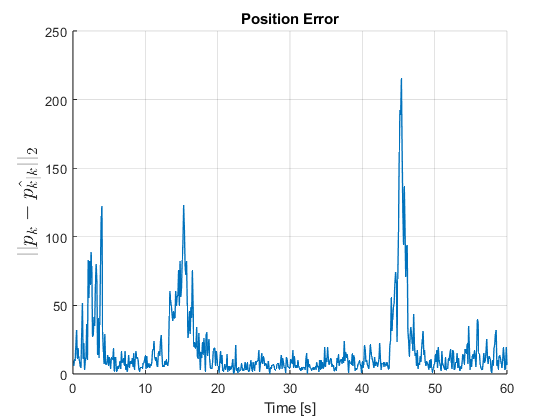



%plot error
figure();
grid on, hold on;
plot( (1:K)*T, vecnorm(xf(1:2,:)-X(1:2,2:end), 2, 1) , 'LineWidth',1)
ylabel('$||p_k - \hat{p_{k|k}}||_2$', 'Interpreter','Latex', 'FontSize',16), xlabel('Time [s]')
title 'Position Error'